## Using MATLAB deep learning toolbox

% I will skip all these as I've explained in detail in test_toolbox_shallow
clc; close; clear;

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.



ind_valid = randperm(size(imgDataTrain, 4), 10000);
ind_train = setxor(1:size(imgDataTrain, 4), ind_valid);

imgDataTrain_ = imgDataTrain(:, :, :, ind_train);
labelsTrain_  = labelsTrain(ind_train);

imgDataValid  = imgDataTrain(:, :, :, ind_valid);
labelsValid   = labelsTrain(ind_valid);

Let's do some data augmentation this time.

The following lines will generated augmented images using X/Y translation, rotation, and scale. Note that these images will not be stored. Network hyperparameters will be trained based on augmented imagedatastore and then dicards the augmented images.

Note that the number of training samples does not change during each epoch. However, during each epoch, the training samples differ slightly as the augmented image datastore applies a random combination of the transformations defined in the imageAugmenter. This is different from what Michael has done--to transform all images and combine the transformed data with orignal data.

imageAugmenter = imageDataAugmenter("RandXTranslation", [-3 3], "RandYTranslation", [-3 3], ...
    "RandRotation", [-20 20], "RandScale", [0.8 1.2]);
augimds = augmentedImageDatastore([28 28 1], imgDataTrain_, labelsTrain_, ...
    'DataAugmentation', imageAugmenter);
augimds.MiniBatchSize = 200;

Let's use the same network structure as what we've tested in the _deep_2 experiment.

Layer = [imageInputLayer([28, 28, 1])
    
    convolution2dLayer(5, 20, 'Stride', 1)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(5, 40, 'Stride', 1)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(100, 'WeightsInitializer', "he")
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10, 'WeightsInitializer', "he")
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
    ];

Train options

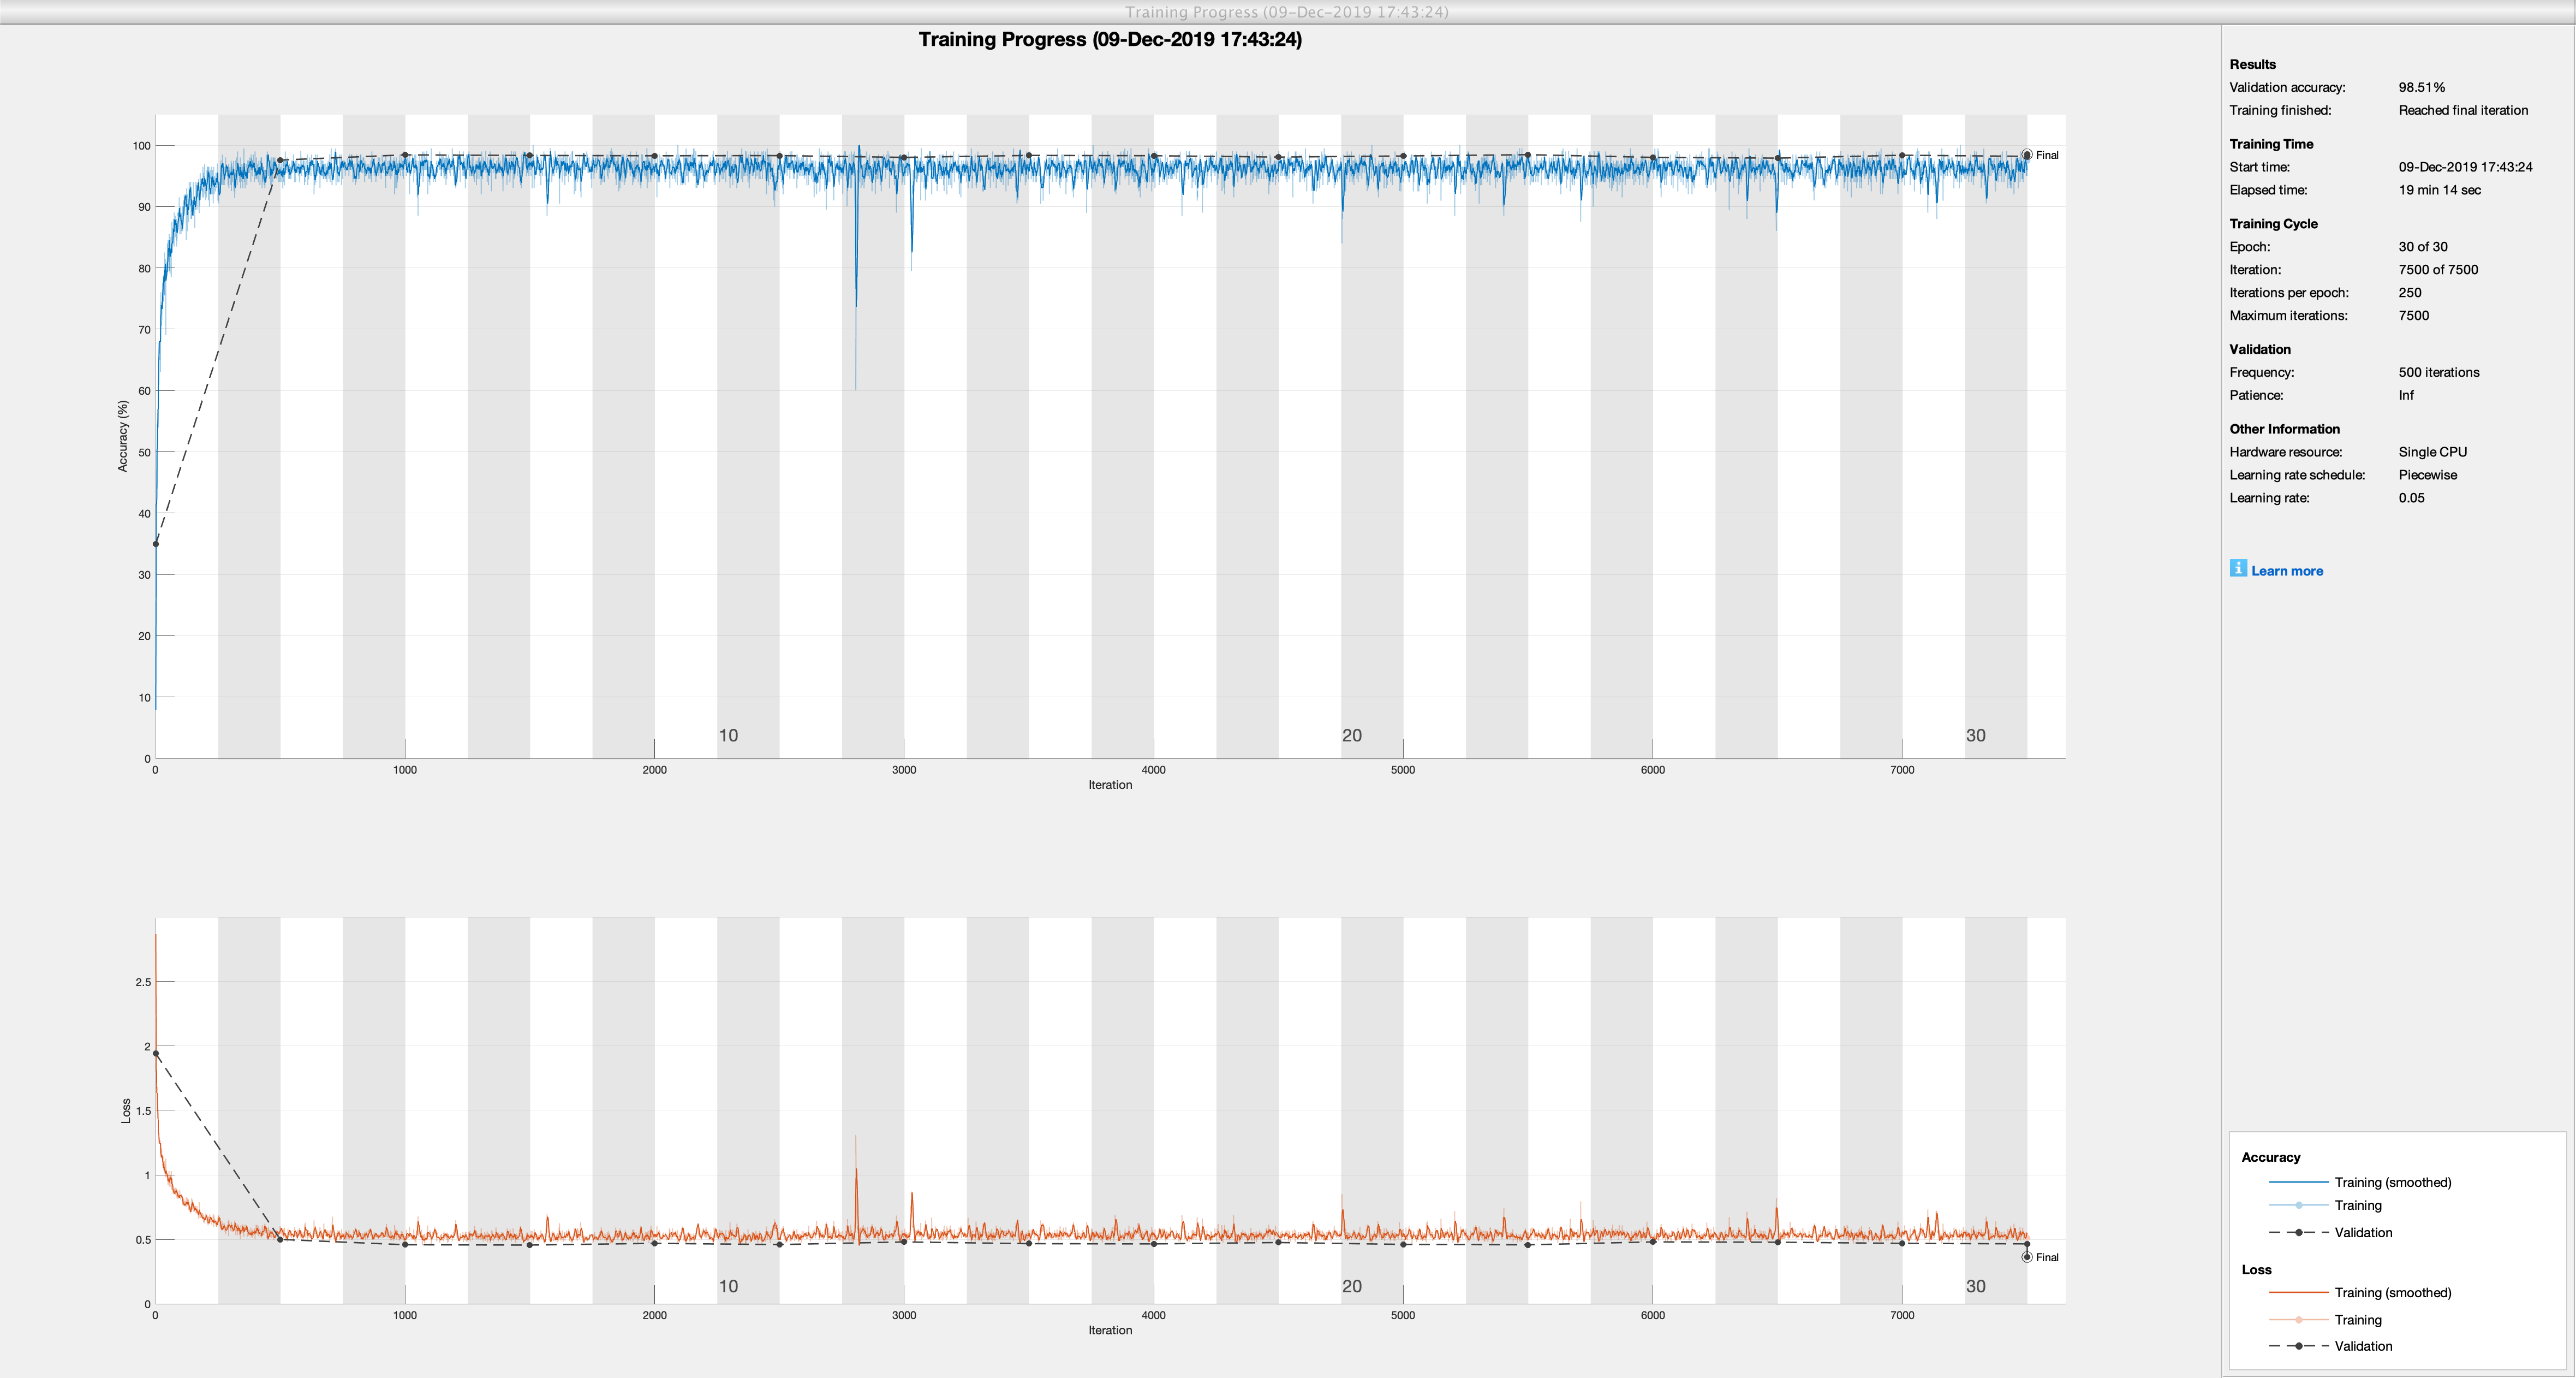

options = trainingOptions('sgdm', 'MaxEpochs', 30, ...
    'Shuffle', 'every-epoch', "MiniBatchSize", 200, ...
    "ValidationData", {imgDataValid(:, :, :, :), labelsValid(:)}, ...
    'ValidationFrequency', 500, ...
    "InitialLearnRate", 0.05, ...
    "LearnRateSchedule", "piecewise", ...
    "LearnRateDropPeriod", 500, ...
    'LearnRateDropFactor', 0.5, ...
    'Momentum', 0.01, ...
    "L2Regularization", 0.1, ...
    "Plots", 'training-progress', ...
    'Verbose', 0);

net = trainNetwork(augimds, Layer, options);

Test accuracy

YPredict  = classify(net, imgDataTest);
accuracy1 = mean(YPredict == labelsTest)

accuracy1 = 0.9880

How about we train this again based on the orignal data without transform (similar idea like "transfer learning") as we never take advantage of the orignal data at all when we use *augimds*? This way we basically also take advantage the orignal data set, making this comparable to Michael's test.

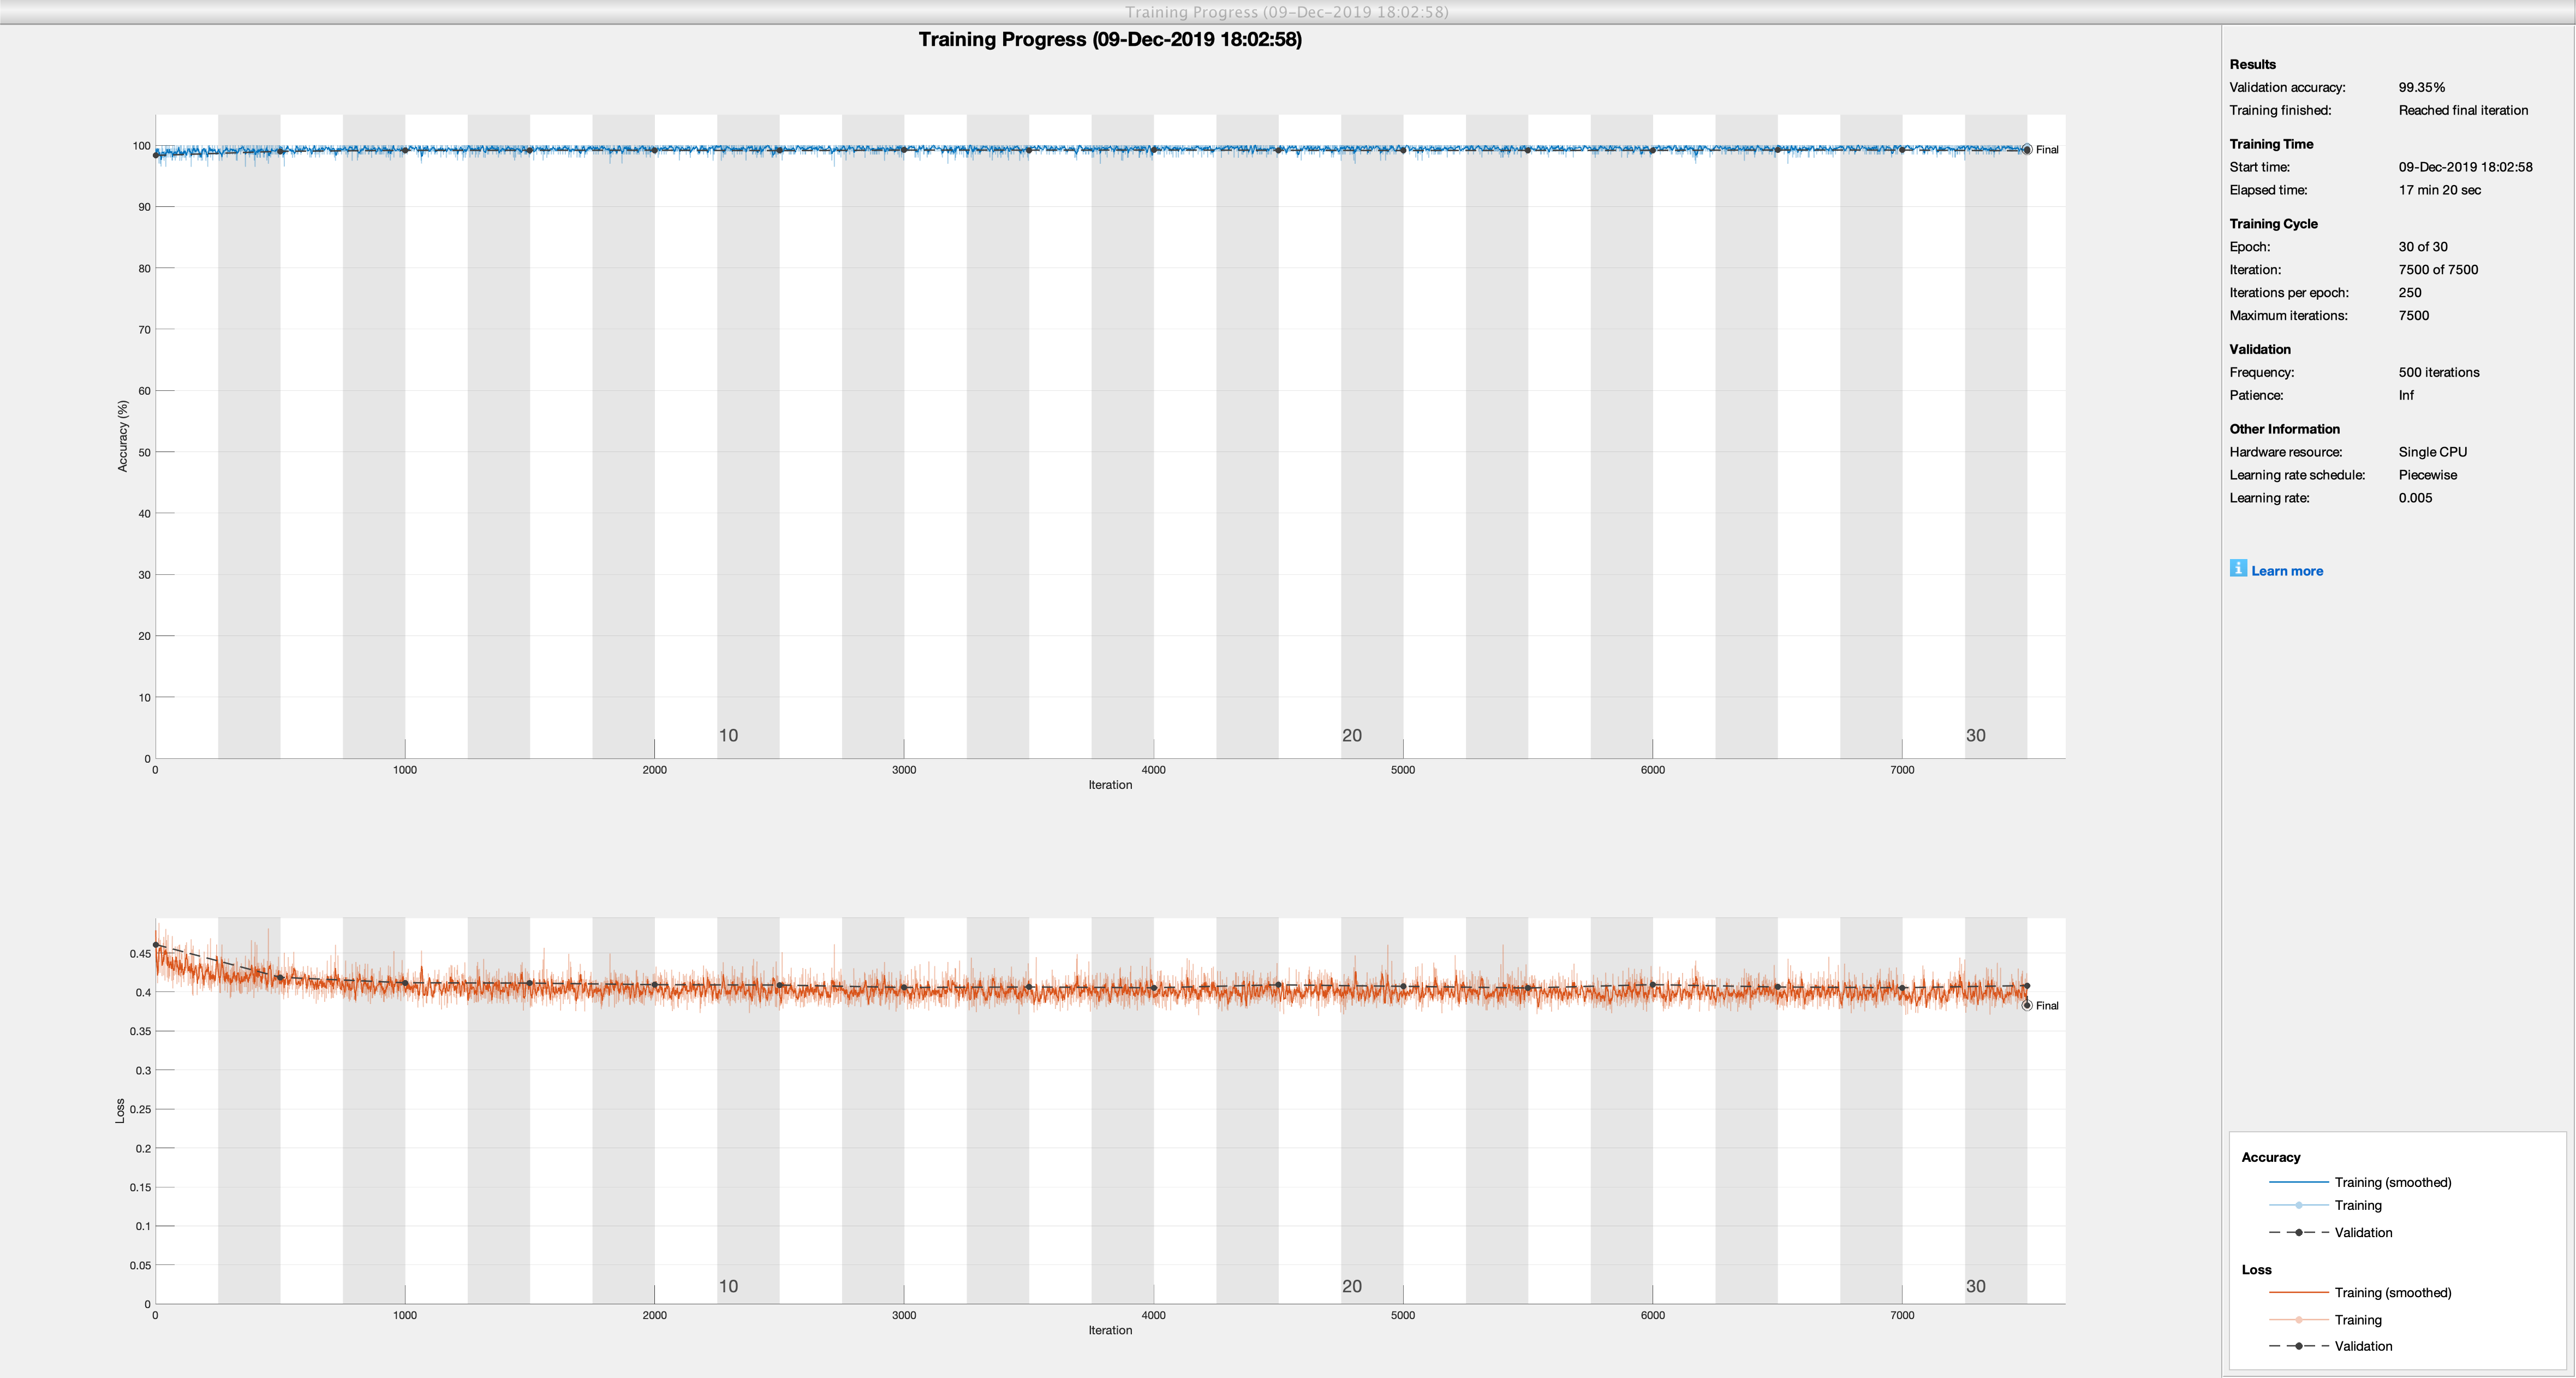

lgraph = layerGraph(net.Layers);

options = trainingOptions('sgdm', 'MaxEpochs', 30, ...
    'Shuffle', 'every-epoch', "MiniBatchSize", 200, ...
    "ValidationData", {imgDataValid(:, :, :, :), labelsValid(:)}, ...
    'ValidationFrequency', 500, ...
    "InitialLearnRate", 0.005, ...
    "LearnRateSchedule", "piecewise", ...
    "LearnRateDropPeriod", 500, ...
    'LearnRateDropFactor', 0.5, ...
    'Momentum', 0.01, ...
    "L2Regularization", 0.1, ...
    "Plots", 'training-progress', ...
    'Verbose', 0);

net = trainNetwork(imgDataTrain_, labelsTrain_, lgraph, options);

Test accuracy

YPredict  = classify(net, imgDataTest);
accuracy2 = mean(YPredict == labelsTest)

accuracy2 = 0.9929

Okay so far the increase looks interesting. My first try got me a 99.4% accuracy on validation data and 99.3% on test data, both being a significant increase from our last try. Data augmentation does provide additional contribution. But you can stil argue that this is because I've actually trained for 60 epochs. So you can shift things around and see. Based on the second picture, it does look like after only 2 epochs of training using the orignal data set, the validation accuracy already goes beyond 99% (roughly).